My Guesses: 

There are sensors everywhere in the $\left\lbrack -10,10\right\rbrack {\;}^3$ cube, each of them are receiving pressure information. 

A Fourier Transform is needed for all the sensor in the cube across all the time domain: $\left\lbrack -10,10\right\rbrack$, and then map it to another data cube in frequcies domain $\left\lbrack \frac{-\pi }{L},\frac{\pi }{L}\right\rbrack$

load TestData.mat
load subdata.mat

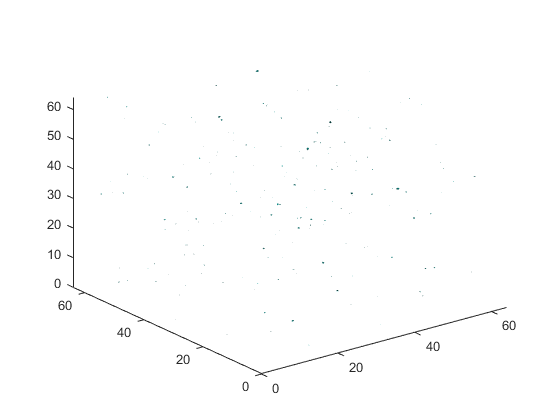

n = 64; L = 10;
Realization1 = subdata(:, 1);
Realization1 = reshape(Realization1, [n, n, n]);
ToCheck = fftn(Realization1);
isosurface(abs(ToCheck)/max(abs(ToCheck), [], "all"), 0.7);

kx = (2*pi/(2*L))*(-n/2: n/2 - 1); k = fftshift(kx);

GetMaxSingal(subdata')

ans = 170707

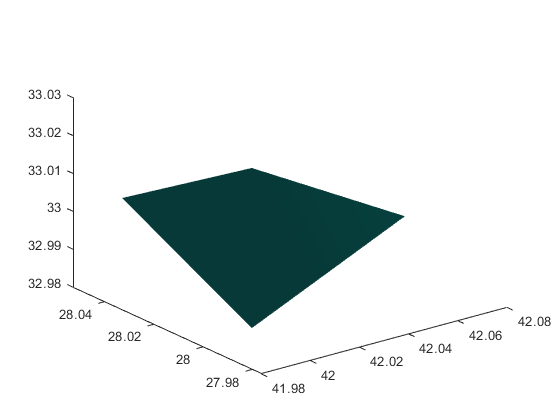

Utave=zeros(n,n,n);
for j=1:size(Undata, 1)
    Un(:,:,:)=reshape(Undata(j,:),n,n,n); 
    %this essentially takes each row of data and chops it into a cube
    Unt=fftn(Un(:,:,:));
    Utave=Utave + Unt;    
end
Utave=fftshift(Utave)/j;
Utave=abs(Utave)/max(abs(Utave), [], 'all');
%scales everything as a ratio of the max value 

 %if the max point in the cube is the signal, 
 %after it is scaled to some portion of 1, the true signal 
 %should lie around the area at or near the max of 1
 close all, isosurface(Utave, 0.99) 

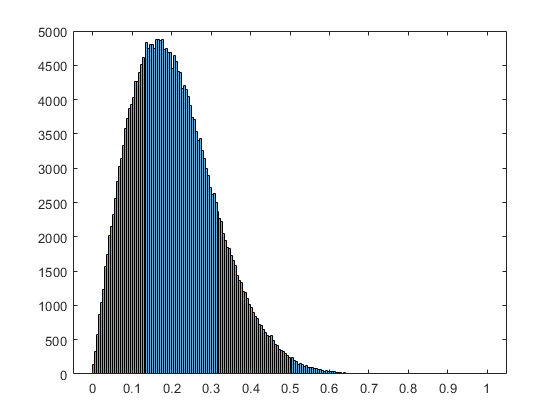

histogram(Utave(:));